clc
clear all

% Read the Excel file into a table
data = readtable('Dynamic Loading.xlsx');

fontName = 'Times New Roman';

%Pulse and Coasting Distance End from Origin:
PulseEnd1 = 97; %(m)
CoastEnd1 = 300; %(m)
PulseEnd2 = 350; %(m)
CoastEnd2 = 370; %(m)
PulseEnd3 = 516; %(m)
CoastEnd3 = 860; %(m)
PulseEnd4 = 880; %(m)
CoastEnd4 = 895; %(m)
PulseEnd5 = 1050;%(m)
CoastEnd5 = 1060;%(m)
PulseEnd6 = 1130;%(m)
CoastEnd6 = 1500;%(m)
PulseEnd7 = 1570;%(m)

PulseCoastDistance = [97 300 350 370 516 860 880 895 1050 1060 1130 1500 1570];
PulseCoastTimeStamps = [16 36 45 47 82 124 128.5 130.5 154.5 156.5 168 212.5 218.5];



## High Duty Cycle:

% Extract relevant data from the filtered table
Time = data.Time1;
Current = data.Current1;
Voltage = data.Voltage1;

% Remove rows where any of Time, Current, or Voltage data points are NaN
validIndices = ~isnan(Time) & ~isnan(Current) & ~isnan(Voltage);
Time = Time(validIndices);
Current = Current(validIndices);
Voltage = Voltage(validIndices);

% Calculate Power using the filtered data
PowerHighDutyCycle = Current .* Voltage;
lapTime = 218; % Lap time in seconds
lapDistance = 1570; % Lap distance in meters

% Proceed with your further analysis or plotting functions
% For example, calculating total time, number of laps, etc.
totalTime = Time(end) - Time(1);
numLaps = floor(totalTime / lapTime);
extraTime = rem(totalTime, lapTime);
totalDistance = numLaps * lapDistance + extraTime / lapTime * lapDistance; % Total distance in meters
totalDistanceKm = totalDistance / 1000; % Convert meters to kilometers

% Calculate total energy consumed
timeSteps = diff(Time);
powerAtIntervals = 0.5 * (PowerHighDutyCycle(1:end-1) + PowerHighDutyCycle(2:end));
totalEnergyJoules = sum(powerAtIntervals .* timeSteps);
totalEnergyKWh = totalEnergyJoules / 3600000; % Convert Joules to kWh

% Calculate efficiency in km per kWh
efficiencyKmPerKWh = totalDistanceKm / totalEnergyKWh;
disp(['Total distance: ', num2str(totalDistanceKm), ' km']);

Total distance: 6.7301 km


disp(['Total energy consumed: ', num2str(totalEnergyJoules), ' Joules, ', num2str(totalEnergyKWh), ' kWh']);

Total energy consumed: 79309.508 Joules, 0.02203 kWh


disp(['Efficiency: ', num2str(efficiencyKmPerKWh), ' km/kWh']);

Efficiency: 305.4919 km/kWh


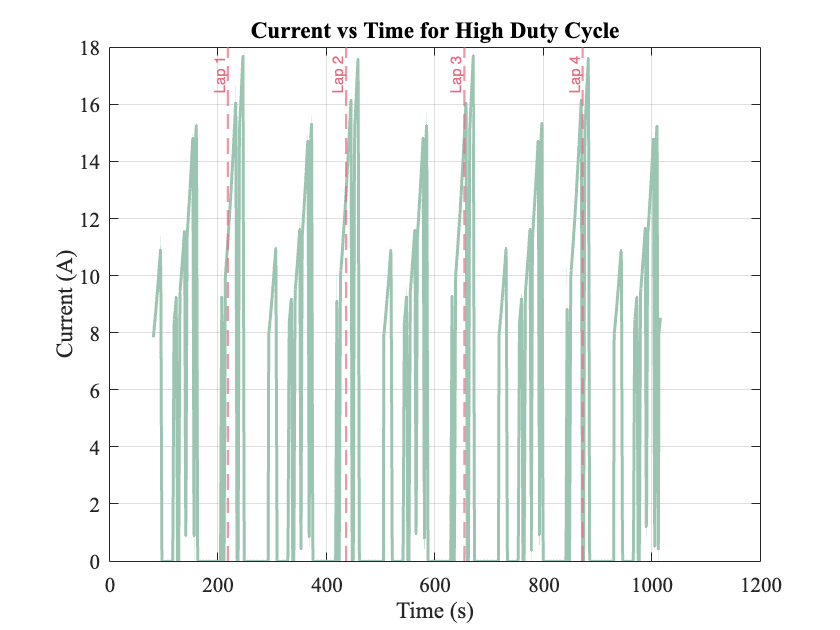



% Plotting current versus time with laps and labels
plotWithLapsAndLabels(Time, Current, 'Current (A)', 'Current vs Time for High Duty Cycle', lapTime, numLaps);

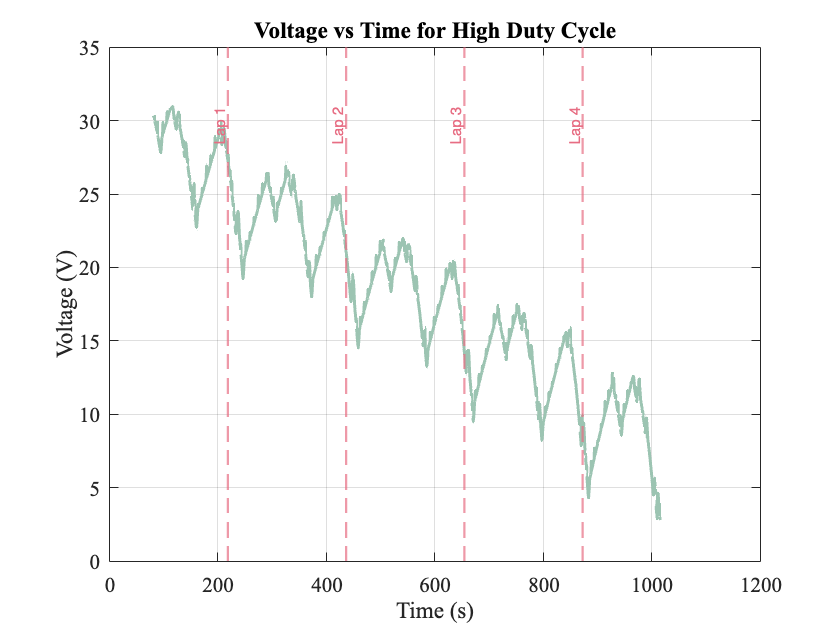


% Plotting voltage versus time with laps and labels
plotWithLapsAndLabels(Time, Voltage, 'Voltage (V)', 'Voltage vs Time for High Duty Cycle', lapTime, numLaps);

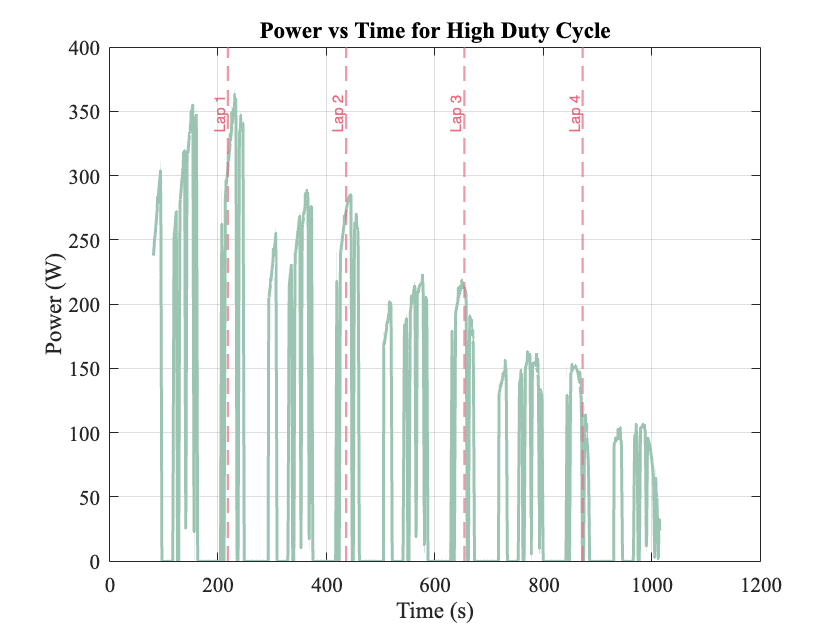


% Plotting power versus time with laps and labels
plotWithLapsAndLabels(Time, PowerHighDutyCycle, 'Power (W)', 'Power vs Time for High Duty Cycle', lapTime, numLaps);

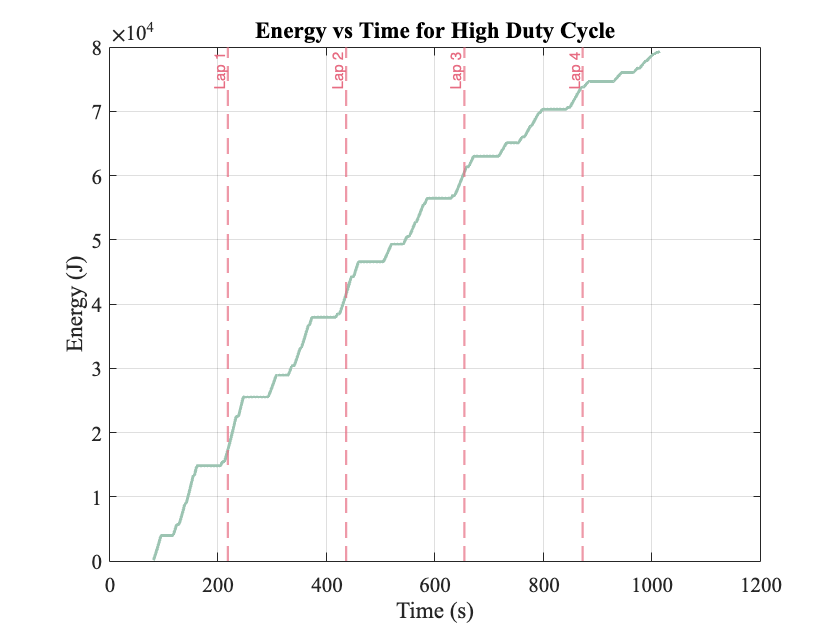

% Function to plot data with vertical lines and lap numbers

% Energy consumption over time (cumulative)
cumulativeEnergyJoules = cumsum(powerAtIntervals .* timeSteps);

% Plotting power versus time with laps and labels
plotWithLapsAndLabels(Time(1:end-1), cumulativeEnergyJoules, 'Energy (J)', 'Energy vs Time for High Duty Cycle', lapTime, numLaps);

## Lower Duty Cycle:

% Extract relevant data from the filtered table
Time = data.Time2;
Current = data.Current2;
Voltage = data.Voltage2;

% Remove rows where any of Time, Current, or Voltage data points are NaN
validIndices = ~isnan(Time) & ~isnan(Current) & ~isnan(Voltage);
Time = Time(validIndices);
Current = Current(validIndices);
Voltage = Voltage(validIndices);

% Calculate Power using the filtered data
PowerHighDutyCycle = Current .* Voltage;
lapTime = 218; % Lap time in seconds
lapDistance = 1570; % Lap distance in meters
numLaps = 10; % Only consider up to the 10th lap

% Time at which the 10th lap ends
endOfTenthLapTime = numLaps * lapTime;

% Restrict data to 10 laps
indicesUpToTenthLap = Time <= endOfTenthLapTime;
Time = Time(indicesUpToTenthLap);
Current = Current(indicesUpToTenthLap);
Voltage = Voltage(indicesUpToTenthLap);
PowerHighDutyCycle = PowerHighDutyCycle(indicesUpToTenthLap);

% Proceed with your further analysis or plotting functions
totalTime = Time(end) - Time(1);
totalDistance = numLaps * lapDistance; % Total distance in meters
totalDistanceKm = totalDistance / 1000; % Convert meters to kilometers

% Calculate total energy consumed
timeSteps = diff(Time);
powerAtIntervals = 0.5 * (PowerHighDutyCycle(1:end-1) + PowerHighDutyCycle(2:end));
totalEnergyJoules = sum(powerAtIntervals .* timeSteps);
totalEnergyKWh = totalEnergyJoules / 3600000; % Convert Joules to kWh

% Calculate efficiency in km per kWh
efficiencyKmPerKWh = totalDistanceKm / totalEnergyKWh;
disp(['Total distance: ', num2str(totalDistanceKm), ' km']);

Total distance: 15.7 km


disp(['Total energy consumed: ', num2str(totalEnergyJoules), ' Joules, ', num2str(totalEnergyKWh), ' kWh']);

Total energy consumed: 258842.1392 Joules, 0.071901 kWh


disp(['Efficiency: ', num2str(efficiencyKmPerKWh), ' km/kWh']);

Efficiency: 218.357 km/kWh


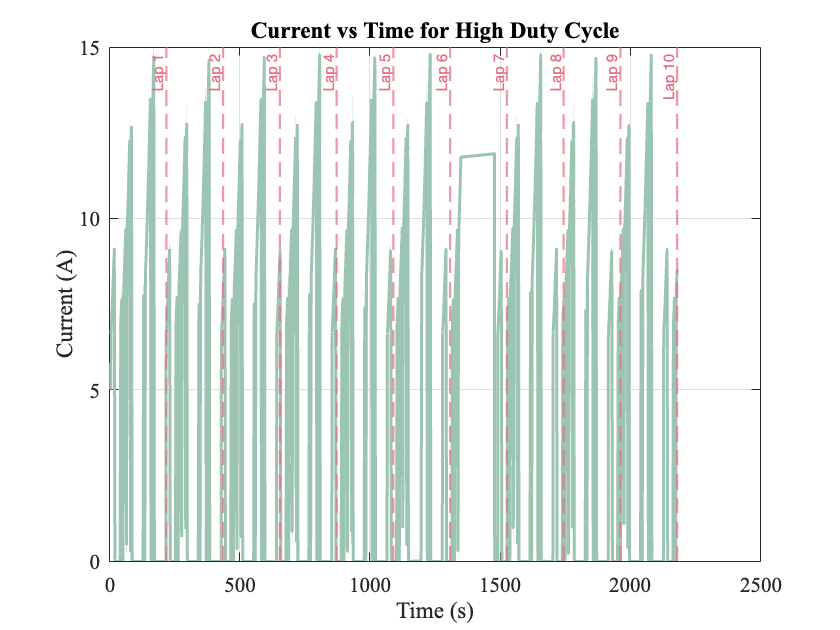



% Plotting current versus time with laps and labels
plotWithLapsAndLabels(Time, Current, 'Current (A)', 'Current vs Time for High Duty Cycle', lapTime, numLaps);

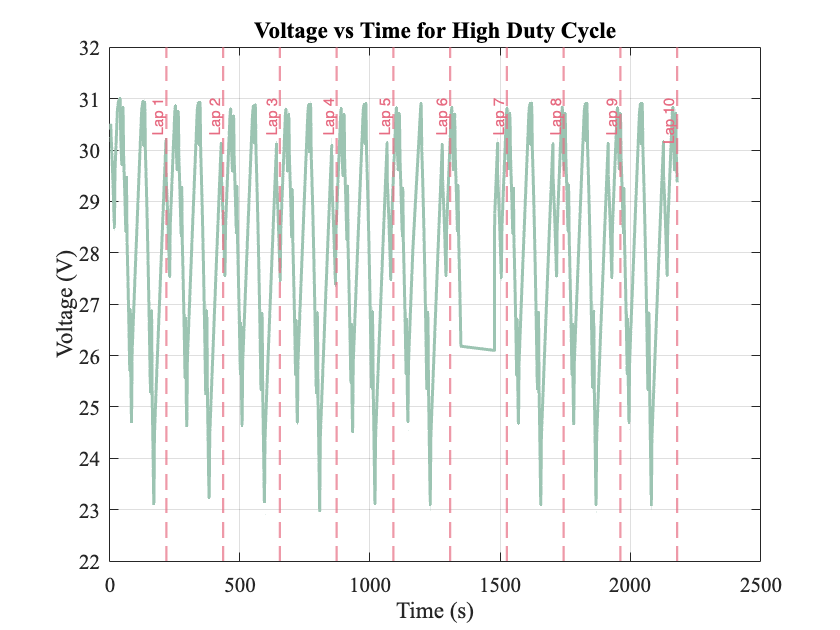


% Plotting voltage versus time with laps and labels
plotWithLapsAndLabels(Time, Voltage, 'Voltage (V)', 'Voltage vs Time for High Duty Cycle', lapTime, numLaps);

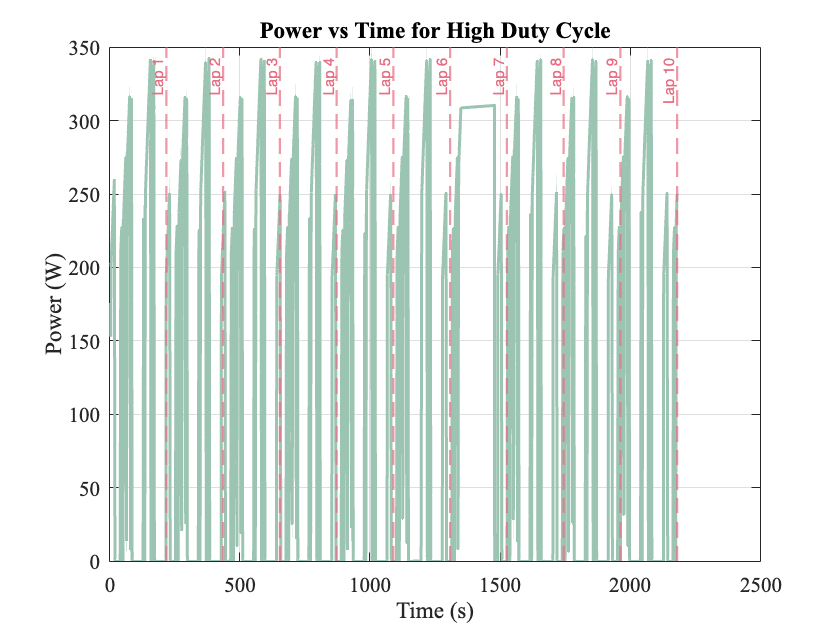


% Plotting power versus time with laps and labels
plotWithLapsAndLabels(Time, PowerHighDutyCycle, 'Power (W)', 'Power vs Time for High Duty Cycle', lapTime, numLaps);

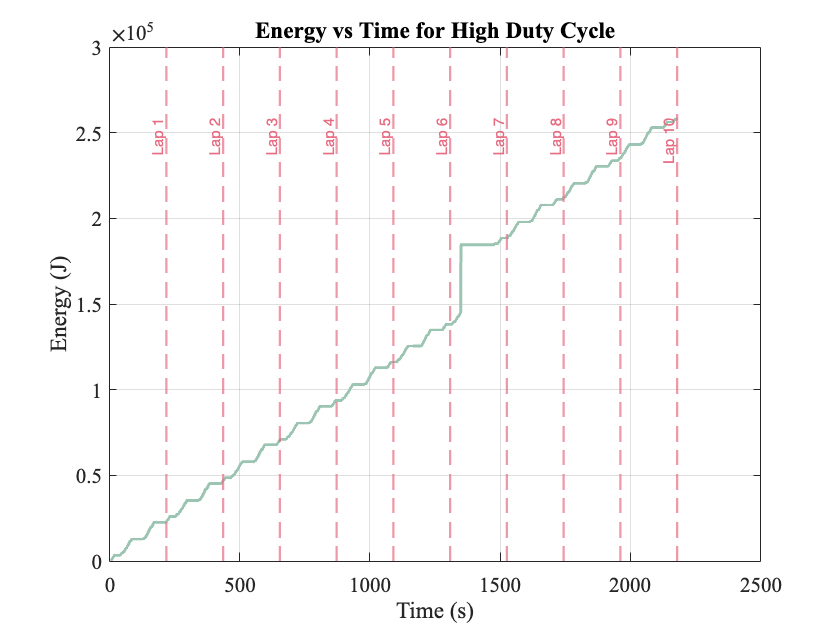

% Function to plot data with vertical lines and lap numbers

% Energy consumption over time (cumulative)
cumulativeEnergyJoules = cumsum(powerAtIntervals .* timeSteps);

% Plotting power versus time with laps and labels
plotWithLapsAndLabels(Time(1:end-1), cumulativeEnergyJoules, 'Energy (J)', 'Energy vs Time for High Duty Cycle', lapTime, numLaps);

## Optimised Duty Cycle Lap: 

% Extract relevant data from the filtered table
Time = data.Time3;
Current = data.Current3;
Voltage = data.Voltage3;

% Remove rows where any of Time, Current, or Voltage data points are NaN
validIndices = ~isnan(Time) & ~isnan(Current) & ~isnan(Voltage);
Time = Time(validIndices);
Current = Current(validIndices);
Voltage = Voltage(validIndices);

% Calculate Power using the filtered data
PowerHighDutyCycle = Current .* Voltage;
lapTime = 218; % Lap time in seconds
lapDistance = 1570; % Lap distance in meters
numLaps = 1; % Only consider up to the 10th lap

% Time at which the 10th lap ends
endOfTenthLapTime = numLaps * lapTime;

% Restrict data to 10 laps
indicesUpToTenthLap = Time <= endOfTenthLapTime;
Time = Time(indicesUpToTenthLap);
Current = Current(indicesUpToTenthLap);
Voltage = Voltage(indicesUpToTenthLap);
PowerHighDutyCycle = PowerHighDutyCycle(indicesUpToTenthLap);

% Proceed with your further analysis or plotting functions
totalTime = Time(end) - Time(1);
totalDistance = numLaps * lapDistance; % Total distance in meters
totalDistanceKm = totalDistance / 1000; % Convert meters to kilometers

% Calculate total energy consumed
timeSteps = diff(Time);
powerAtIntervals = 0.5 * (PowerHighDutyCycle(1:end-1) + PowerHighDutyCycle(2:end));
totalEnergyJoules = sum(powerAtIntervals .* timeSteps);
totalEnergyKWh = totalEnergyJoules / 3600000; % Convert Joules to kWh

% Calculate efficiency in km per kWh
efficiencyKmPerKWh = totalDistanceKm / totalEnergyKWh;
disp(['Total distance: ', num2str(totalDistanceKm), ' km']);

Total distance: 1.57 km


disp(['Total energy consumed: ', num2str(totalEnergyJoules), ' Joules, ', num2str(totalEnergyKWh), ' kWh']);

Total energy consumed: 23835.1698 Joules, 0.0066209 kWh


disp(['Efficiency: ', num2str(efficiencyKmPerKWh), ' km/kWh']);

Efficiency: 237.1286 km/kWh


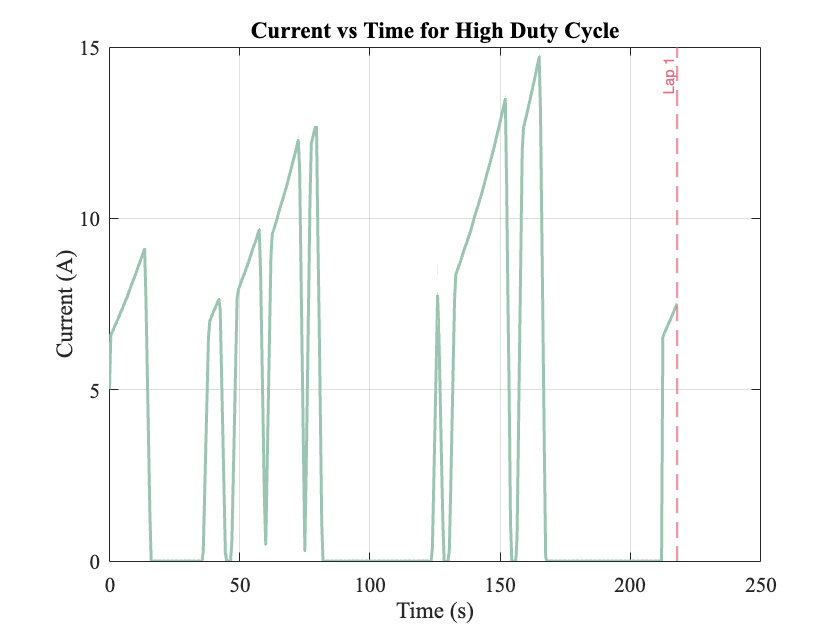



% Plotting current versus time with laps and labels
plotWithLapsAndLabels(Time, Current, 'Current (A)', 'Current vs Time for High Duty Cycle', lapTime, numLaps);

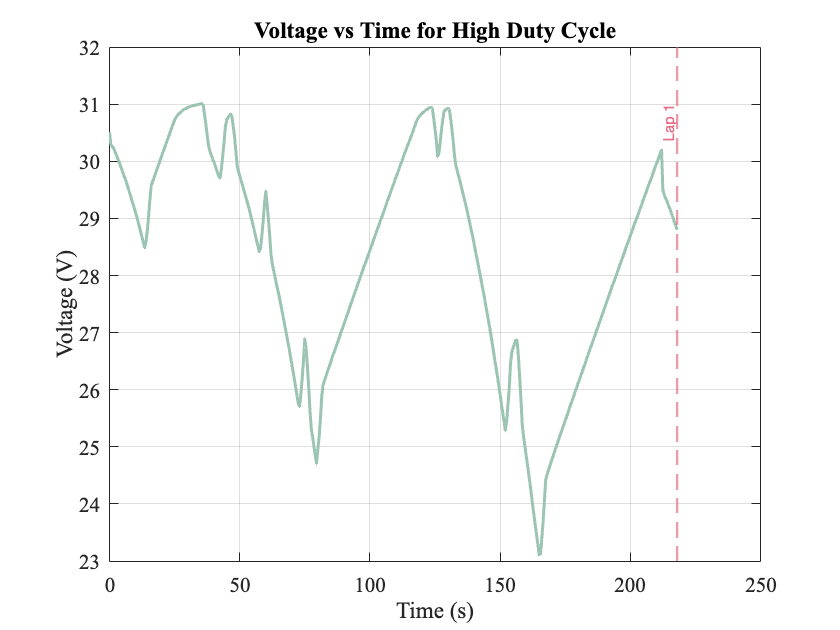


% Plotting voltage versus time with laps and labels
plotWithLapsAndLabels(Time, Voltage, 'Voltage (V)', 'Voltage vs Time for High Duty Cycle', lapTime, numLaps);

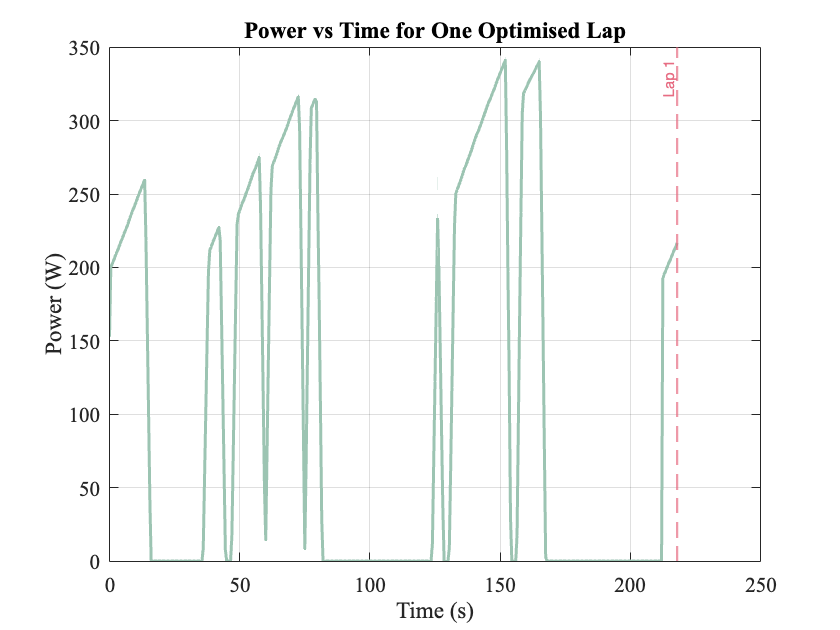


% Plotting power versus time with laps and labels
plotWithLapsAndLabels(Time, PowerHighDutyCycle, 'Power (W)', 'Power vs Time for One Optimised Lap', lapTime, numLaps);

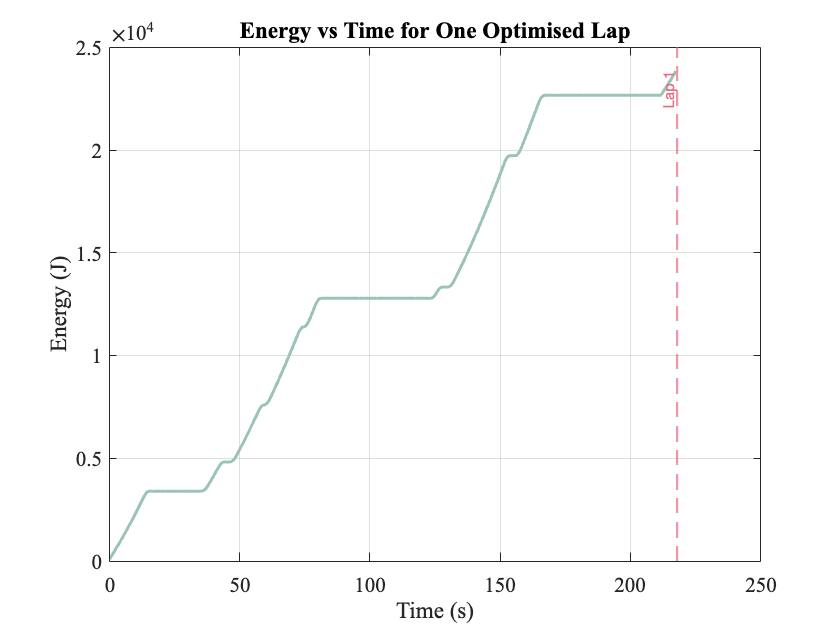

% Function to plot data with vertical lines and lap numbers

% Energy consumption over time (cumulative)
cumulativeEnergyJoules = cumsum(powerAtIntervals .* timeSteps);

% Plotting power versus time with laps and labels
plotWithLapsAndLabels(Time(1:end-1), cumulativeEnergyJoules, 'Energy (J)', 'Energy vs Time for One Optimised Lap', lapTime, numLaps);

## Super Capacitor State of Charge

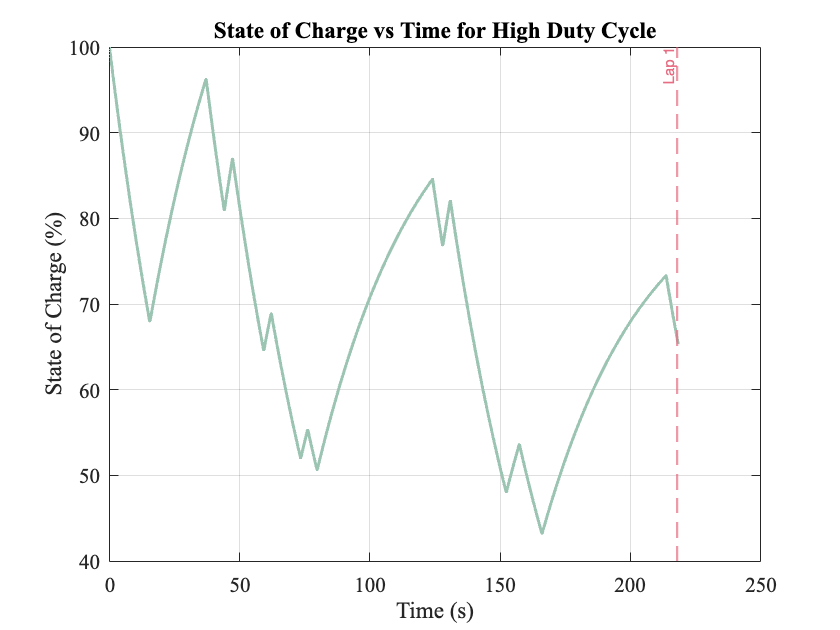

% Extract relevant data from the filtered table
Time = data.Time4;
StateofCharge = data.StateofCharge;

% Remove rows where any of Time, Current, or Voltage data points are NaN
validIndices = ~isnan(Time) & ~isnan(StateofCharge);
Time = Time(validIndices);
StateofCharge = StateofCharge(validIndices);

% Calculate Power using the filtered data
PowerHighDutyCycle = Current .* Voltage;
lapTime = 218; % Lap time in seconds
lapDistance = 1570; % Lap distance in meters
numLaps = 1; % Only consider up to the 10th lap

% Time at which the 10th lap ends
endOfTenthLapTime = numLaps * lapTime;

% Plotting current versus time with laps and labels
plotWithLapsAndLabels(Time, StateofCharge, 'State of Charge (%)', 'State of Charge vs Time for High Duty Cycle', lapTime, numLaps);

## Super Capacitor State of Energy

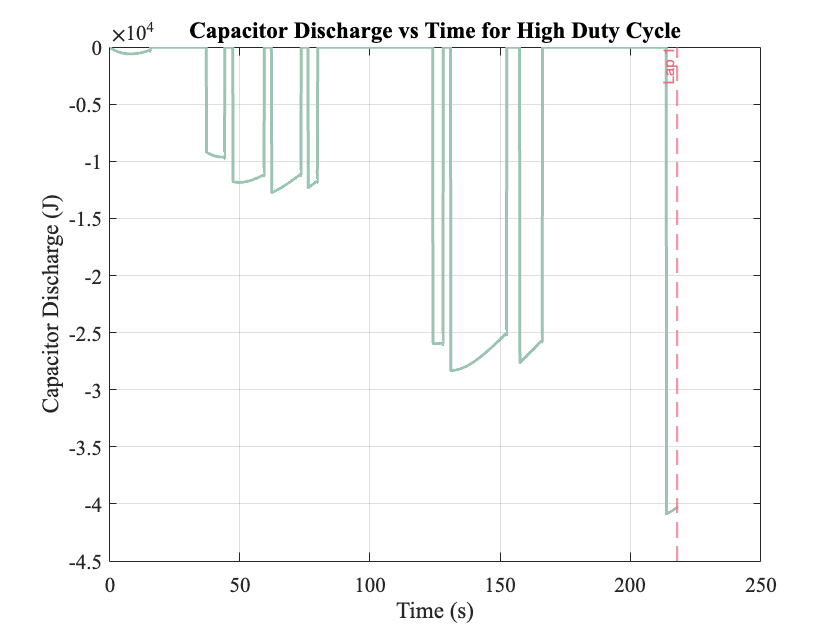

% Extract relevant data from the filtered table
Time = data.Time5;
StateofEnergy = data.CumulativeEnergy;

% Remove rows where any of Time, Current, or Voltage data points are NaN
validIndices = ~isnan(Time) & ~isnan(StateofEnergy);
Time = Time(validIndices);
StateofEnergy = StateofEnergy(validIndices);

% Calculate Power using the filtered data
PowerHighDutyCycle = Current .* Voltage;
lapTime = 218; % Lap time in seconds
lapDistance = 1570; % Lap distance in meters
numLaps = 1; % Only consider up to the 10th lap

% Time at which the 10th lap ends
endOfTenthLapTime = numLaps * lapTime;

% Plotting current versus time with laps and labels
plotWithLapsAndLabels(Time, StateofEnergy, 'Capacitor Discharge (J)', 'Capacitor Discharge vs Time for High Duty Cycle', lapTime, numLaps);
hold off

## Analysis:

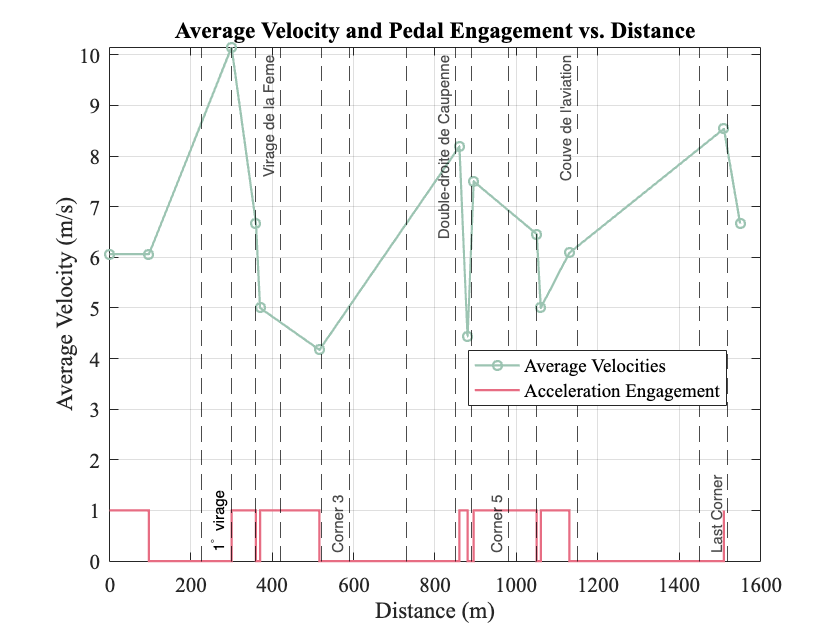

% Given data
PulseCoastDistance = [0 97 300 360 370 516 860 880 895 1050 1060 1130 1510 1550];
PulseCoastTimeStamps = [0 16 36 45 47 82 124 128.5 130.5 154.5 156.5 168 212.5 218.5];

%Corners: 
Corner1Entry = 227; %(m)
Corner1Exit = 300; %(m)
Corner2Entry = 360; %(m)
Corner2Exit = 420; %(m)
Corner3Entry = 520; %(m)
Corner3Exit = 590; %(m)
Corner4Entry = 730; %(m)
Corner4Exit = 850; %(m)
Corner5Entry = 890; %(m)
Corner5Exit = 980; %(m)
Corner6Entry = 1050; %(m)
Corner6Exit = 1150; %(m)
Corner7Entry = 1450; %(m)
Corner7Exit = 1520; %(m)

% Calculate average velocity for each segment
for i = 2:length(PulseCoastDistance)
    deltaDistance = PulseCoastDistance(i) - PulseCoastDistance(i-1);
    deltaTime = PulseCoastTimeStamps(i) - PulseCoastTimeStamps(i-1);
    averageVelocities(i-1) = deltaDistance / deltaTime;
end

% Add the first value to the beginning of the averageVelocities array
averageVelocities = [averageVelocities(1), averageVelocities];

% Plot the average velocities and the polynomial fitting
figure;
plot(PulseCoastDistance(1:(end)), averageVelocities, '-o', 'LineWidth', 1.5, 'Color', "#9CC4B2"); hold on;
xlabel('Midpoint Distance (m)'); % adding axis label for clarity
ylabel('Average Velocity (m/s)'); % adding axis label for clarity
title('Average Segment Velocities with Polynomial Fitting');
% Set the y-axis to start from 0
ylim([0 inf]); % inf automatically adjusts the upper limit based on data


% Corner Names and distances: 
xline(Corner1Entry, '--', 'Color', 'k', 'LabelHorizontalAlignment', 'left', 'LabelVerticalAlignment', 'bottom', 'HandleVisibility', 'off');
xline(Corner1Exit, '--', '1^{\circ} virage', 'Color', 'k', 'LabelHorizontalAlignment', 'left', 'LabelVerticalAlignment', 'bottom', 'HandleVisibility', 'off');
xline(Corner2Entry, '--', 'Color', 'k', 'LabelHorizontalAlignment', 'left', 'LabelVerticalAlignment', 'top', 'HandleVisibility', 'off');
xline(Corner2Exit, '--', 'Virage de la Feme', 'Color', 'k', 'LabelHorizontalAlignment', 'left', 'LabelVerticalAlignment', 'top', 'HandleVisibility', 'off');
xline(Corner3Entry, '--', 'Color', 'k', 'LabelHorizontalAlignment', 'left', 'LabelVerticalAlignment', 'bottom', 'HandleVisibility', 'off');
xline(Corner3Exit, '--', 'Corner 3', 'Color', 'k', 'LabelHorizontalAlignment', 'left', 'LabelVerticalAlignment', 'bottom', 'HandleVisibility', 'off');
xline(Corner4Entry, '--', 'Color', 'k', 'LabelHorizontalAlignment', 'left', 'LabelVerticalAlignment', 'top', 'HandleVisibility', 'off');
xline(Corner4Exit, '--', 'Double-droite de Caupenne', 'Color', 'k', 'LabelHorizontalAlignment', 'left', 'LabelVerticalAlignment', 'top', 'HandleVisibility', 'off');
xline(Corner5Entry, '--', 'Color', 'k', 'LabelHorizontalAlignment', 'left', 'LabelVerticalAlignment', 'bottom', 'HandleVisibility', 'off');
xline(Corner5Exit, '--', 'Corner 5', 'Color', 'k', 'LabelHorizontalAlignment', 'left', 'LabelVerticalAlignment', 'bottom', 'HandleVisibility', 'off');
xline(Corner6Entry, '--', 'Color', 'k', 'LabelHorizontalAlignment', 'left', 'LabelVerticalAlignment', 'top', 'HandleVisibility', 'off');
xline(Corner6Exit, '--', "Couve de l'aviation", 'Color', 'k', 'LabelHorizontalAlignment', 'left', 'LabelVerticalAlignment', 'top', 'HandleVisibility', 'off');
xline(Corner7Entry, '--', 'Color', 'k', 'LabelHorizontalAlignment', 'left', 'LabelVerticalAlignment', 'top', 'HandleVisibility', 'off');
xline(Corner7Exit, '--', 'Last Corner', 'Color', 'k', 'LabelHorizontalAlignment', 'left', 'LabelVerticalAlignment', 'bottom', 'HandleVisibility', 'off');

% Initialize pedal engagement array
pedalEngagement = zeros(1, length(PulseCoastDistance)-1);

% Define pulse segments (where car is accelerating) - assuming even-indexed segments are pulse
% and odd-indexed are coast based on your description
for i = 1:2:length(pedalEngagement)
    pedalEngagement(i) = 1;
end

% Add a secondary y-axis for pedal engagement
stairs(PulseCoastDistance(1:end-1), pedalEngagement, 'LineWidth', 1.5,  'Color', "#E76D83"); % Stairs plot for pedal engagement

% Set labels and grid
title('Average Velocity and Pedal Engagement vs. Distance')
xlabel('Distance (m)')
ylabel('Average Velocity (m/s)')
legend('Average Velocities', 'Acceleration Engagement', 'Location', 'best');
grid on;
set(gca, 'FontSize', 14, 'FontName', fontName);
hold off

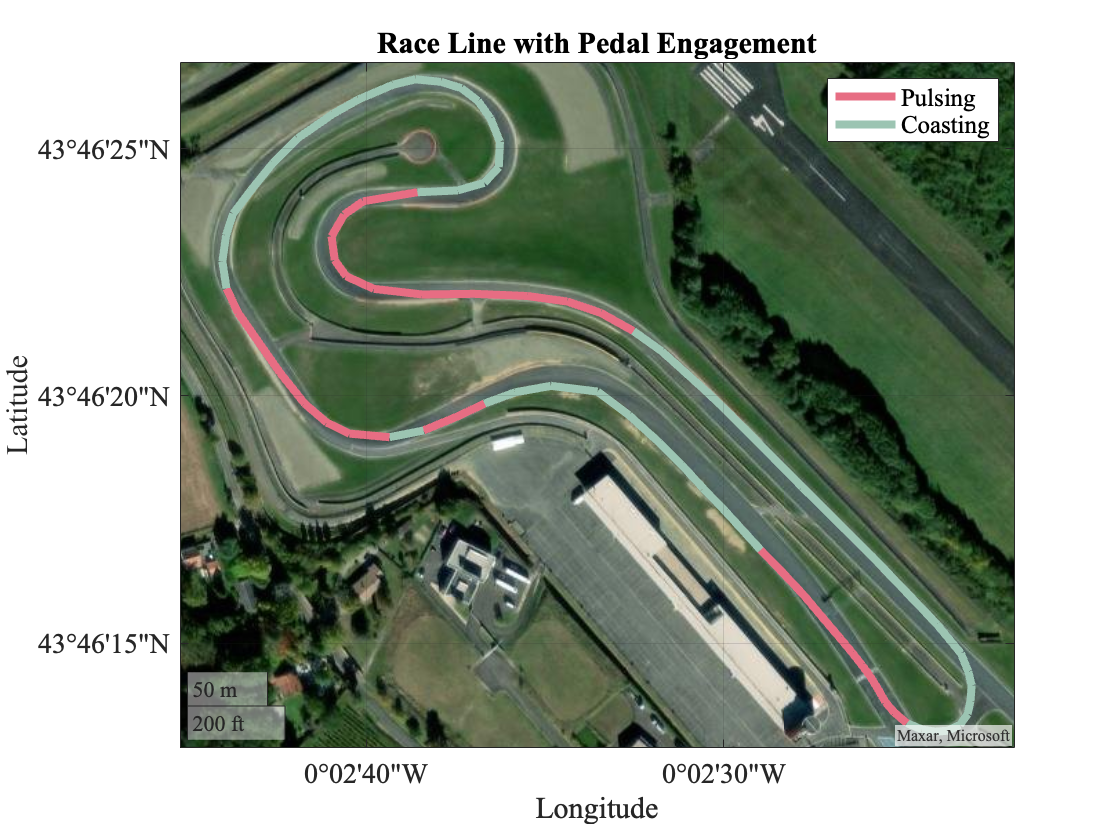


% Read the Excel file into a table
GoogleEarthData = readtable('NogaroLap.xlsx');

LONG = GoogleEarthData.LONG;
LAT = GoogleEarthData.LAT;

% Calculate the cumulative distances between consecutive GPS coordinates
earthRadius = 6371000; % Radius of the Earth in meters
cumulativeDistance = zeros(1, length(LAT));
for k = 2:length(LAT)
    dLat = deg2rad(LAT(k) - LAT(k-1));
    dLon = deg2rad(LONG(k) - LONG(k-1));
    a = sin(dLat/2)^2 + cos(deg2rad(LAT(k-1))) * cos(deg2rad(LAT(k))) * sin(dLon/2)^2;
    c = 2 * atan2(sqrt(a), sqrt(1-a));
    distance = earthRadius * c;
    cumulativeDistance(k) = cumulativeDistance(k-1) + distance;
end

% Determine pedal engagement based on the cumulative distances
pedalEngagement = zeros(1, length(cumulativeDistance));
for i = 1:length(PulseCoastDistance)-1
    idxStart = find(cumulativeDistance >= PulseCoastDistance(i), 1, 'first');
    idxEnd = find(cumulativeDistance < PulseCoastDistance(i+1), 1, 'last');
    if mod(i, 2) == 1  % Assuming pulsing happens in odd indexed segments
        pedalEngagement(idxStart:idxEnd) = 1;
    end
end

% Initialize the map figure with geographic axes
figure;
geoaxes;

% Set the basemap to 'satellite'
geobasemap satellite;

% Plot each segment with color based on pulsing (1) or coasting (0)
hold on;
for i = 1:length(pedalEngagement)-1
    if pedalEngagement(i) == 1
        % Pulsing segment - plot with one color (e.g., 'b' for blue)
        h1 = geoplot([LAT(i) LAT(i+1)], [LONG(i) LONG(i+1)],  'Color', "#E76D83", 'LineWidth', 4);
    else
        % Coasting segment - plot with another color (e.g., 'r' for red)
        h2 = geoplot([LAT(i) LAT(i+1)], [LONG(i) LONG(i+1)], 'Color', "#9CC4B2", 'LineWidth', 4);
    end
end

% Set the legend manually if not already set
if exist('h1', 'var') && exist('h2', 'var')
    legend([h1, h2], {'Pulsing', 'Coasting'});
end

title('Race Line with Pedal Engagement');
set(gca, 'FontSize', 14, 'FontName', fontName);
grid on;

function plotWithLapsAndLabels(x, y, yLabel, titleText, lapTime, numLaps)
    fontName = 'Times New Roman';
    figure;
    hold on;
    plot(x, y, 'LineWidth', 2, 'Color', "#9CC4B2");  % Thicker line for better visibility
    maxY = max(y);  % Find maximum Y to place text correctly

    for i = 1 : numLaps
        lapX = lapTime * i;
        xline(lapX, '--',  'Color', "#E76D83",'LineWidth', 1.5);  % Red dashed line for each lap
        % Adjusting text position to be on the left and vertical
        text(lapX, maxY, sprintf('Lap %d', i), 'Color', "#E76D83", 'FontSize', 10, 'Rotation', 90, 'HorizontalAlignment', 'right', 'VerticalAlignment', 'bottom');  % Place lap number vertically
    end

    grid on;  % Adding grid
    title(titleText);
    xlabel('Time (s)');
    ylabel(yLabel);
    set(gca, 'FontSize', 14, 'FontName', fontName);  % Larger font size for better readability
end
